## **Limpiar variables**

 
clear

## Valores iniciales

**Posición del robot**

x = 0;
y = 0;
z = 0;
p_robot = [x; y; z];

**Orientación del robot**

phi = 0;    %Rotación en el eje X
theta = 0;  %Rotación en el eje Y
psi = 0;    %Rotación en el eje Z
ori_robot = deg2rad([phi; theta; psi]);
secuencia = "XYZ";

**Matriz de transformación homogenea inicial**

R_inicial = euler2rotMat(ori_robot,secuencia);
A0 = [R_inicial  p_robot
      zeros(1,3) 1];

**Crear estructura del robot en base a la tabla DH y los valores iniciales**

dh = readtable('datos\tabla_DH\robot1.csv');
robot = crear_robot(dh,A0);

**Trayectoria cartesiana del robot**

p = readtable("datos\trayectorias\cargar_trayectoria_1.csv");
n = length(p.x);
R_puntos = zeros(3,3,n);
for i = 1:n
    euler_puntos = deg2rad([p.phi(i);p.theta(i);p.psi(i)]);
    R_puntos(:,:,i) = euler2rotMat(euler_puntos,secuencia);
end
pos_puntos = [p.x';p.y';p.z'];
z_puntos = R_puntos(:,3,:);
 

## **Cinemática inversa de los puntos**

tol = 1e-6;
max_iter = 100;
alpha = 1.0;
numSamples = 9; % Esto sirve para buscar diferentes puntos en caso de llegar a un mínimo local
q_sol = zeros(robot.NGDL,n);
p_sol = zeros(size(pos_puntos));
for i = 1:n
%     [q_sol(:,i),p_sol(:,i)] = cinematica_inv(robot, pos_puntos(:,i), z_puntos(:,i), tol, max_iter, alpha, numSamples); % Con rotación
    [q_sol(:,i),p_sol(:,i)] = cinematica_inv(robot, pos_puntos(:,i), tol, max_iter, alpha, numSamples);
end

Solución alcanzada en muestra 1, iteraciones 63, error = 9.227668e-07
Solución alcanzada en muestra 1, iteraciones 6, error = 1.359620e-12


## **Trayectoria de punto articular a punto articular**

% Calcular la diferencia entre la configuración final y la inicial para cada junta
delta_q = abs(q_sol(:,2) - q_sol(:,1));
% Usar el valor más alto de los tiempos mínimos requeridos para cada junta,
% de forma que siempre sea un perfil triangular.
t_final = max(2 * delta_q ./ robot.dqMax);
% Muestras para graficar trayectoria
numSamples = 201;

[q, dq, ddq, t, pp] = trapveltraj(q_sol, numSamples, ...
                                            'Acceleration', robot.ddqMax, ...
                                            'EndTime', t_final);

## Cinemática diferencial

**Inicializar variables**

posicion = zeros(3,length(t));
orientacion = posicion;
vel_linear = posicion;
vel_angular = posicion;
acel_linear = posicion;
acel_angular = posicion;
R = zeros(3,3,length(t));
Jv = zeros(3,robot.NGDL,length(t));
dJv = Jv;
Jw = Jv;
dJw = Jw;

**Calcular velocidad y aceleración**

Algo que cabe destacar es que se realizarán cálculos discretos, por lo que en vez de una función $f\left(t\right)$, donde podemos sustiruir por ejemplo $t=2s$, aquí usaremos los índices $k$, los  cuales se refieren a los índices del vector de tiempo que corresponden al tiempo actual $t\left(k\right)$, a un tiempo anterior $t\left(k-1\right)$ o al tiempo siguiente $t\left(k+1\right)$.

for k = 1:length(t)

**            Actualiza la configuración del robot con los valores articulares **$q\left(k\right)$

    robot = actualizar_robot_completo(robot, q(:,k));

**            Extraer la posición y orientación del efector final**

    posicion(:,k) = robot.T(1:3,4,end);
    R(:,:,k) = robot.T(1:3,1:3,end);

**            Obtener la orientación en ángulos de Euler a partir de la matriz R del efector final**

    orientacion(:,k) = rotMat2euler(R(:, :, k),secuencia);

**            Calcular el Jacobiano geométrico a partir de la transformación global**

    [Jv(:,:,k),Jw(:,:,k)] = jac_geometrico_completo(robot);

**            Calcular la velocidad lineal y angular**

####             
$$v=J\dot{q}$$


    vel_linear(:,k)  = Jv(:,:,k)*dq(:,k);
    vel_angular(:,k) = Jw(:,:,k)*dq(:,k);

**            Calcular la derivada temporal del Jacobiano usando diferencias finitas**

    if k > 1
        dt = t(k) - t(k-1);
        dJv(:,:,k) = (Jv(:,:,k) - Jv(:,:,k-1)) / dt;
        dJw(:,:,k) = (Jw(:,:,k) - Jw(:,:,k-1)) / dt;
    end

**            Calcular la aceleración lineal y angular**

####             
$$a=\frac{d}{\textrm{dt}}\left(J\dot{q} \right)=J\ddot{q} +\dot{J} \dot{q}$$


    acel_linear(:,k) = Jv(:,:,k)*ddq(:,k) + dJv(:,:,k)*dq(:,k);
    acel_angular(:,k) = Jw(:,:,k)*ddq(:,k) + dJw(:,:,k)*dq(:,k);
end

## Animación

Si solo vas a imprimir la gráfica, debes usar 30 fps (la mitad de los que dice la gráfica).

close all
fps = 30;

t_animacion = 0:1/fps:t_final;
animSamples = length(t_animacion);

**Crear estructura gráfica del robot**

g = crear_grafica_robot();

**Generar el nombre del archivo con fecha y hora actual**

nombre_video = sprintf('resultados/animaciones/cinematica_directa_robot1_%s.avi', datestr(now, 'yyyy-mm-dd_HH-MM-SS'));

**Comenta las siguientes lineas si no quieres generar el video**

% videoObj = VideoWriter(nombre_video);
% videoObj.FrameRate = fps;
% open(videoObj);

**Generar animación**

q_anim = zeros(robot.NGDL,1);
for k = 1:length(t_animacion)
% for k = 1:n
%     robot = actualizar_robot(robot, q_anim(:,k));
    for i = 1:robot.NGDL
        q_anim(i) = ppval(cell2mat(pp(i)),t_animacion(k));
    end
    robot = actualizar_robot_completo(robot, q_anim);
    g = dibujar_robot(g, robot);
    

**            Capturar el fotograma actual y escribirlo en el video (comenta si no quieres generar video)**

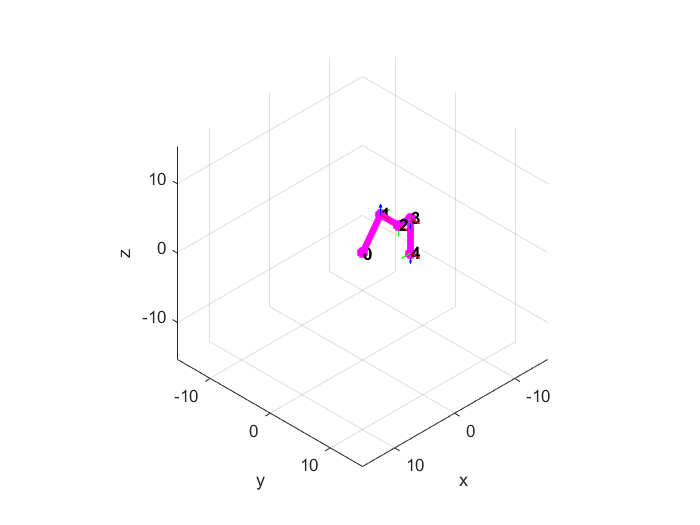

%     frame = getframe(gcf);
%     writeVideo(videoObj, frame);
end

## **Gráficas**

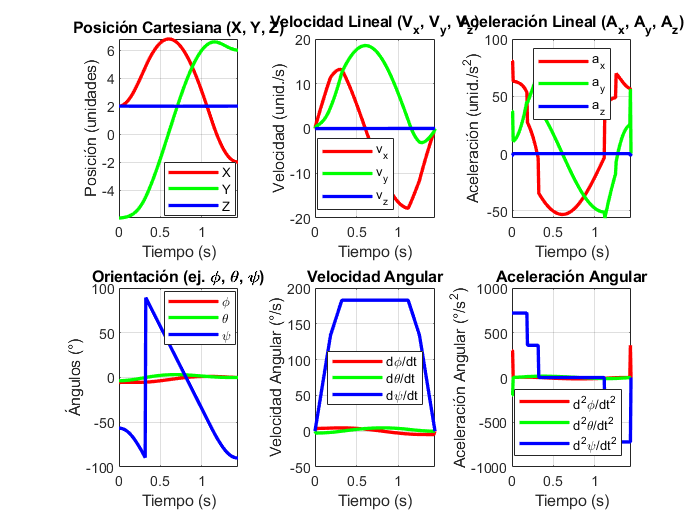

plotCartesian(t, posicion, vel_linear, acel_linear, orientacion, vel_angular, acel_angular)

**Cinemática articular**

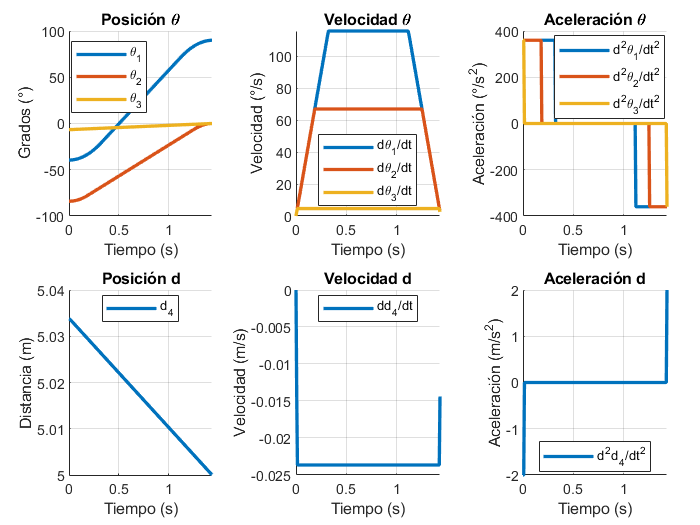

plotJoints(robot,t,q,dq,ddq)